dr = 1;
R_a = 220;
R_b = 1:dr:2*10^6;
uC = [1 2.2 3.3 4.7 10] .* 10^-6;
nC = [1 2.2 4.7 10 22 47 100 220 470] .* 10^-9;
pC = [1 2.2 4.7 10 22 47 100 220 470] .* 10^-12;
test_C = [1 2.2 4.7 10 22 47 100 470 1000] .* 10^-9;
R_E12 = [1 1.2 1.5 1.8 2.2 3.3 3.9 4.7 5.6 6.8 8.2];


## Frequency

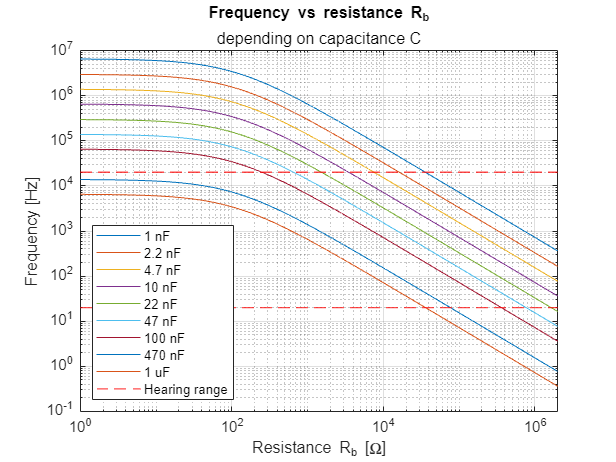

plotfvsR(R_a, R_b, test_C);

## Duty cycle

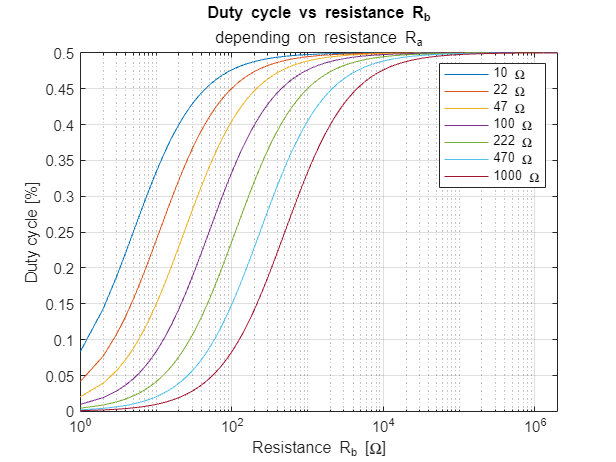

test_R_a = [10 22 47 100 222 470 1000];
for r_a = 1:size(test_R_a, 2)
    dc = duty_cycle(test_R_a(r_a), R_b);    
    semilogx(R_b, dc, "DisplayName", join([string(test_R_a(r_a)) "\Omega"]));
    hold on;
end
legend("show");
title("Duty cycle vs resistance R_b");
subtitle("depending on resistance R_a");
xlabel("Resistance R_b [\Omega]");
ylabel("Duty cycle [%]");
grid on;
hold off;

## resistor current

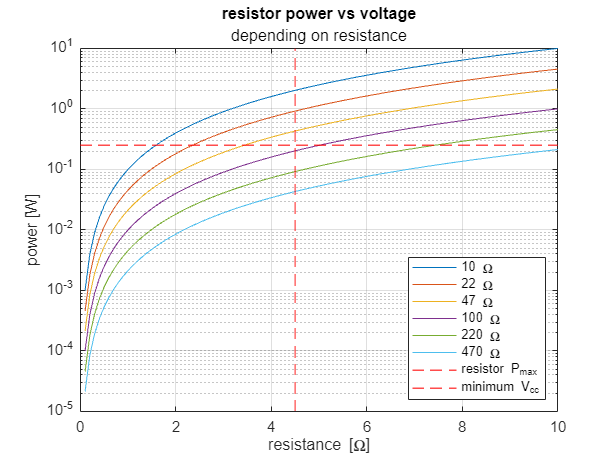

test_R = [10 22 47 100 220 470];
dV = 0.1;
V = 0:dV:10;
for a = 1:size(test_R, 2)
    power = V.^2/test_R(a);
    semilogy(V, power, "DisplayName",join([string(test_R(a)) "\Omega"]));
    hold on;
end
legend("show", Location="southeast");
yline(0.25, "DisplayName", "resistor P_{max}", "Color","red", "LineWidth", 1, "LineStyle","--");
xline(4.5,  "DisplayName", "minimum V_{cc}", "Color","red", "LineWidth", 1, "LineStyle","--")
title("resistor power vs voltage")
subtitle("depending on resistance")
xlabel("resistance [\Omega]")
ylabel("power [W]")
grid on;
hold off;

## notes

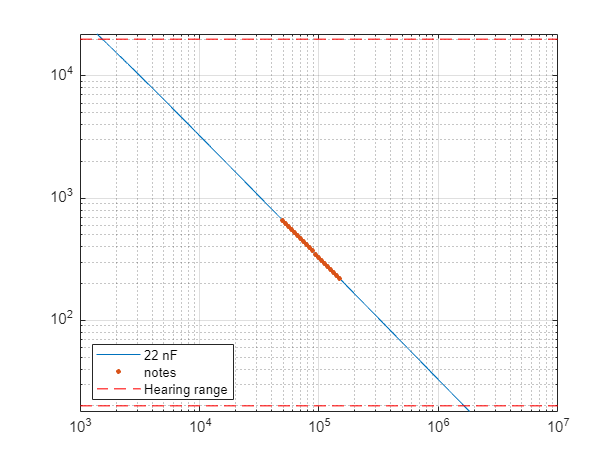

A_4 = 440;
note_names = ["C", "C#", "D", "D#", "E", "F", "F#", "G", "G#", "A", "A#", "B"];
c = 22 * 10^-9;
r_b = 1000:2*10^6;
r_a = 220;
notes = MIDInote(57:76);
% notes = MIDInote(17:76);
notes_resistance = inverse_period(notes, r_a, c);
T = period(r_a, r_b, c);
frequency = 1./T;
loglog(r_b, frequency, "DisplayName", "22 nF");
hold on;
loglog(notes_resistance, notes, ".", "DisplayName", "notes", MarkerSize=10);
legend("Location","southwest")
yline(20000, "Color","red", "LineWidth", 1, "LineStyle","--", "DisplayName", "Hearing range");
yline(20, "Color","red", "LineWidth", 1, "LineStyle","--", "HandleVisibility","off");
ylim([18 22000]);
grid on;
hold off;

## notes diffrence

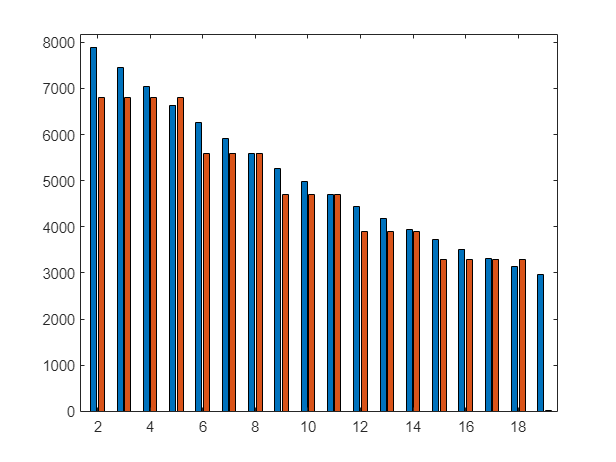

notes_resistance_difference = 1:size(notes_resistance, 2);
notes_nearest_resistor = 1:size(notes_resistance, 2);
% notes_resistance_difference(1) = notes_resistance(1);
for r_multiplier = [1 10 100 1000 10000 100000 1000000]
    for k = 1:(size(notes_resistance, 2)-1)
        notes_resistance_difference(k) = notes_resistance(k) - notes_resistance(k+1);
        temp = interp1(R_E12 .* r_multiplier, R_E12 .* r_multiplier, notes_resistance_difference(k), "nearest");
        if temp >= 0
            notes_nearest_resistor(k - 1) = temp; 
        end
    end
end
bar_plot = [notes_resistance_difference; notes_nearest_resistor];
bar(bar_plot')